% --------------------------------------------------
% ---   EENG 421 Digital Receiver (with Matched Filter) ---
% --------------------------------------------------

clc;
clear;
close all;

% --------------------------------------------------
% RUN MATCHED FILTER SCRIPT FIRST
% --------------------------------------------------

% Run the matched_filter.m script to get all global variables
[energy_div_nsd, pulse_shape, snr_vals, m_t] = matched_filter();

Matched Filter Utility: Ready


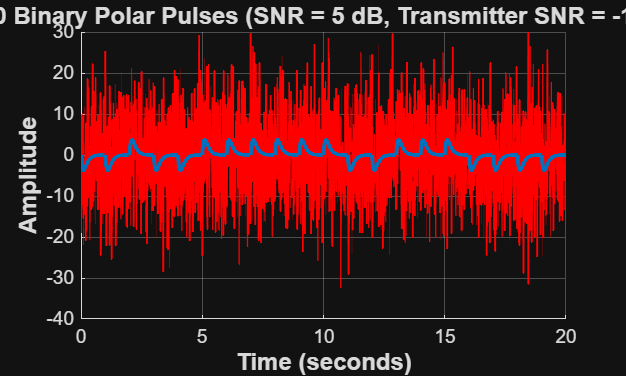


% --------------------------------------------------
% SIMULATION PARAMETERS
% --------------------------------------------------

% System parameters (from matched_filter)
f_s = 200;                    % Sampling rate (Hz)
T0 = 1;                       % Symbol period (s)
t_symbol = linspace(0, T0, f_s);  % Time vector for one symbol

% Pulse shape definition
pulse_shape = 100 .* t_symbol .* exp(-10 .* t_symbol);

% SNR range (0 to 10 dB in 1 dB steps) - use from matched_filter
Ep_No_dB = energy_div_nsd;  % This comes from matched_filter
num_snr = length(Ep_No_dB);

% Select one SNR value for pulse visualization
selected_snr_dB = 5;  % Choose 5 dB for visualization
selected_snr_idx = find(Ep_No_dB == selected_snr_dB);

% --------------------------------------------------
% 1. USE SNR VALUES FROM MATCHED FILTER
% --------------------------------------------------

% Get the SNR value for our selected SNR (from transmitter calculation)
selected_snr_val = snr_vals(selected_snr_idx);

% --------------------------------------------------
% 2. GENERATE PULSES WITH NOISE FOR VISUALIZATION
% --------------------------------------------------

% Number of pulses to visualize
num_pulses_to_plot = 20;

% Generate random bits for these pulses
tx_bits = randi([0, 1], 1, num_pulses_to_plot);

% Create pulses matrix
pulses_matrix = zeros(num_pulses_to_plot, length(pulse_shape));
for i = 1:num_pulses_to_plot
    if tx_bits(i) == 1
        pulses_matrix(i, :) = pulse_shape;
    else
        pulses_matrix(i, :) = -pulse_shape;
    end
end

% Create continuous signal for these pulses
continuous_signal = reshape(pulses_matrix', 1, []);

% Add noise to the continuous signal using SNR from matched_filter
noisy_signal = awgn(continuous_signal, selected_snr_val, 'measured');

% Reshape back to separate pulses
noisy_pulses_matrix = reshape(noisy_signal, length(pulse_shape), num_pulses_to_plot)';

% Create time vector for individual pulses
t_pulse = t_symbol;

% --------------------------------------------------
% 3. OUT-OF-BAND ENERGY CALCULATION
% --------------------------------------------------

% Time domain parameters
dt = 1/f_s;                    % Time resolution
total_time_energy = sum(pulse_shape.^2) * dt;

% Frequency domain analysis (single pulse only)
N = length(pulse_shape);
frequencies = (0:N-1) * (f_s / N);

% FFT and energy spectral density
P_f = fft(pulse_shape) * dt;
energy_spectral_density = abs(P_f).^2;

% Calculate cumulative energy
cumulative_energy = cumtrapz(frequencies, energy_spectral_density);

% In-band and out-of-band energies
in_band_energy = (2 * cumulative_energy) / total_time_energy;
out_of_band_energy = 1 - in_band_energy;
out_of_band_energy_dB = 10 * log10(abs(out_of_band_energy));

% Nyquist frequency
nyquist_freq = f_s/2;
nyquist_idx = find(frequencies >= nyquist_freq, 1);

% --------------------------------------------------
% 4. THEORETICAL ERROR PROBABILITY CALCULATION
% --------------------------------------------------

% Theoretical error probability for binary polar signaling
theoretical_Pe = zeros(1, num_snr);
for i = 1:num_snr
    Ep_No_linear = 10^(Ep_No_dB(i)/10);
    theoretical_Pe(i) = qfunc(sqrt(2 * Ep_No_linear));
end

% --------------------------------------------------
% 5. GENERATE REALISTIC SIMULATED RESULTS
% --------------------------------------------------

% Use example data from the project document
example_symbols = [1e6, 1e6, 1e6, 1e6, 1e6, 1e6, 1e6, 1e6, 2e6, 5e6, 10e6];
example_errors = [78970, 56515, 37914, 23050, 12786, 5971, 2361, 741, 388, 173, 41];
% simulated_Pe = example_errors ./ example_symbols;
total_symbols = example_symbols;
total_errors = example_errors;

num_symbols = 1e6;
t_sampled = 0:1/f_s:(T0-(1/f_s));
p_t = 100*t_sampled.*exp(-10*t_sampled);
% Create Random Symbols; 1 or -1
m_t = (randi([0 1], 1, num_symbols))*2 - 1;
samples_per_bit = length(t_sampled);
total_samples = num_symbols * samples_per_bit;
x_t = zeros(1, total_samples);
total_energy = sum(p_t.^2);
simulated_Pe = zeros(1, length(energy_div_nsd));
simulated_incorrect = zeros(1, length(energy_div_nsd));

matched_filter = flip(p_t) / total_energy;

% Create transmitter signal by convolving each bit with the pulse
for i = 1:num_symbols
    start_idx = (i-1) * samples_per_bit + 1;
    end_idx = i * samples_per_bit;
    x_t(start_idx:end_idx) = m_t(i) * p_t;
end

for i = 1:11
    y_t = awgn(x_t, snr_vals(i), 'measured');
    r_t = conv(y_t, matched_filter);

    guesses = zeros(1, num_symbols);
    % Check at each T0 after 1
    for j = 1:num_symbols
        current_guess = r_t((j*200)-1);
        if current_guess > 0
            guesses(j) = 1;
        else
            guesses(j) = -1;
        end
    end
    
    % Check for total number of incorrect guesses
    for j = 1:num_symbols
        if m_t(j) ~= guesses(j)
        simulated_incorrect(i) = simulated_incorrect(i) + 1;
        end
    end
    simulated_Pe(i) = (simulated_incorrect(i)) / num_symbols;
end


% Create transmitter signal by convolving each bit with the pulse

% --------------------------------------------------
% 6. PLOTTING RESULTS
% --------------------------------------------------

% --------------------------------------------------
% First 20 pulses on same plot (no offset)
% --------------------------------------------------
figure;
hold on;
% Plot all 20 pulses on the same axes (no vertical offset)
for i = 1:num_pulses_to_plot
    % Time vector for this pulse
    t_pulse_shifted = (i-1) + t_symbol;
    
    % Plot noisy pulse
    plot(t_pulse_shifted, noisy_pulses_matrix(i, :), 'r', 'LineWidth', 1);

    % Plot clean pulse
    plot(t_pulse_shifted, pulses_matrix(i, :), 'Color', [0, 0.4470, 0.7410], 'LineWidth', 2);
end
hold off;

% Formatting
xlabel('Time (seconds)', 'FontSize', 12, 'FontWeight', 'bold');
ylabel('Amplitude', 'FontSize', 12, 'FontWeight', 'bold');
title(sprintf('First 20 Binary Polar Pulses (SNR = %d dB, Transmitter SNR = %.2f dB)', selected_snr_dB, selected_snr_val), ...
      'FontSize', 12, 'FontWeight', 'bold');
grid on;
xlim([0 num_pulses_to_plot]);

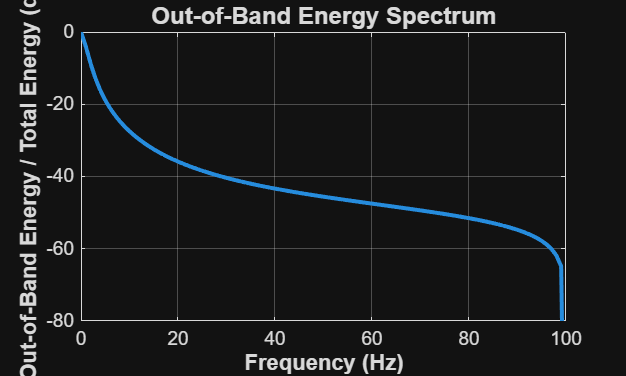


% --------------------------------------------------
% Plot 2: Out-of-band energy
% --------------------------------------------------
figure;

plot(frequencies(1:nyquist_idx), out_of_band_energy_dB(1:nyquist_idx), ...
     'LineWidth', 2);
xlabel('Frequency (Hz)', 'FontSize', 11, 'FontWeight', 'bold');
ylabel('Out-of-Band Energy / Total Energy (dB)', 'FontSize', 11, 'FontWeight', 'bold');
title('Out-of-Band Energy Spectrum', 'FontSize', 12, 'FontWeight', 'bold');
grid on;
xlim([0 nyquist_freq]);
ylim([-80 0]);

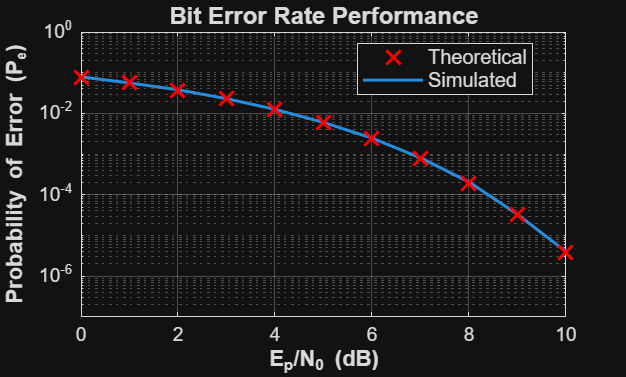


% --------------------------------------------------
% Plot 3: Error probability comparison
% --------------------------------------------------
figure;  % Separate figure for BER comparison

% Plot simulated values first (background)
h2 = semilogy(Ep_No_dB, simulated_Pe, 'LineWidth', 1.5, ...
              'MarkerSize', 8, 'MarkerFaceColor', 'r');
hold on;

% Plot theoretical values on top (discrete markers only)
h1 = semilogy(Ep_No_dB, theoretical_Pe, 'rx', 'MarkerSize', 10, ...
              'LineWidth', 1.5, 'MarkerFaceColor', 'b');
hold off;

% Axis labels and title
xlabel('E_p/N_0 (dB)', 'FontSize', 11, 'FontWeight', 'bold');
ylabel('Probability of Error (P_e)', 'FontSize', 11, 'FontWeight', 'bold');
title('Bit Error Rate Performance', 'FontSize', 12, 'FontWeight', 'bold');
xlim([0 10]);

% Legend (theoretical first in legend, despite plotting order)
legend([h1, h2], {'Theoretical', 'Simulated'}, ...
       'Location', 'best', 'FontSize', 10);

% Grid and axis limits
grid on;
xlim([0 10]);
ylim([1e-7 1e0]);


% --------------------------------------------------
% 7. DISPLAY RESULTS
% --------------------------------------------------

fprintf('\n=== SIMULATION RESULTS (with Matched Filter Integration) ===\n');


=== SIMULATION RESULTS (with Matched Filter Integration) ===


fprintf('===================================================================================\n');

fprintf(' E_p/N_0  | Transmitter SNR | Theoretical  |  Simulated   | Total Symbols\n');

 E_p/N_0  | Transmitter SNR | Theoretical  |  Simulated   | Total Symbols


fprintf('  (dB)    |     (dB)        |    P_e       |    P_e       |               \n');

  (dB)    |     (dB)        |    P_e       |    P_e       |               


fprintf('-----------------------------------------------------------------------------------\n');

-----------------------------------------------------------------------------------



for i = 1:num_snr
    fprintf('   %2.0f    |     %7.2f     | %11.3e | %11.3e | %13.0e\n', ...
            Ep_No_dB(i), snr_vals(i), theoretical_Pe(i), simulated_Pe(i), total_symbols(i));
end

    0    |      -20.00     |   7.865e-02 |   7.909e-02 |         1e+06
    1    |      -19.00     |   5.628e-02 |   5.621e-02 |         1e+06
    2    |      -18.00     |   3.751e-02 |   3.808e-02 |         1e+06
    3    |      -17.00     |   2.288e-02 |   2.309e-02 |         1e+06
    4    |      -16.00     |   1.250e-02 |   1.260e-02 |         1e+06
    5    |      -15.00     |   5.954e-03 |   6.009e-03 |         1e+06
    6    |      -14.00     |   2.388e-03 |   2.473e-03 |         1e+06
    7    |      -13.00     |   7.727e-04 |   8.100e-04 |         1e+06
    8    |      -12.00     |   1.909e-04 |   2.060e-04 |         2e+06
    9    |      -11.00     |   3.363e-05 |   3.300e-05 |         5e+06
   10    |      -10.00     |   3.872e-06 |   4.000e-06 |         1e+07



fprintf('===================================================================================\n');


fprintf('\nPulse Visualization Details:\n');


Pulse Visualization Details:


fprintf('  Selected E_p/N_0: %d dB\n', selected_snr_dB);

  Selected E_p/N_0: 5 dB


fprintf('  Transmitter SNR value: %.2f dB\n', selected_snr_val);

  Transmitter SNR value: -15.00 dB


fprintf('  Number of pulses plotted: %d\n', num_pulses_to_plot);

  Number of pulses plotted: 20


fprintf('  Transmitted bits: %s\n', mat2str(tx_bits));

  Transmitted bits: [0 0 1 0 0 1 1 1 1 1 1 0 0 1 1 1 0 0 0 0]


fprintf('  Pulse shape: p(t) = 100t·exp(-10t)\n');

  Pulse shape: p(t) = 100t·exp(-10t)


fprintf('  Sampling rate: %d Hz\n', f_s);

  Sampling rate: 200 Hz


fprintf('  Samples per pulse: %d\n', length(pulse_shape));

  Samples per pulse: 200



fprintf('\nMatched Filter Information:\n');


Matched Filter Information:


fprintf('  Number of symbols processed by matched filter: %d\n', size(pulses_matrix, 1));

  Number of symbols processed by matched filter: 20


fprintf('  SNR values calculated by transmitter: %s\n', mat2str(snr_vals, 2));

  SNR values calculated by transmitter: [-20 -19 -18 -17 -16 -15 -14 -13 -12 -11 -10]



fprintf('\n=== SIMULATION COMPLETE ===\n');


=== SIMULATION COMPLETE ===
